clc;
clear all;
clearvars;
close all;
A=xlsread('C:\Abolfazl\Research\PhD\cases 3mar2021\Result2\Result2.xlsx','Pol'); 
year_numbers=[1:size(A(:,1))-1]';

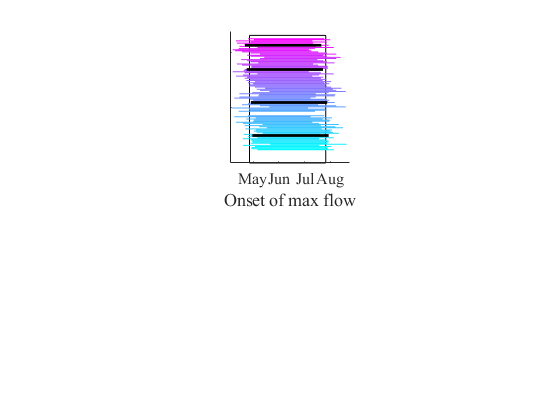

close all;
aa=2;
subplot(2,3,2)
area([mean(A(:,aa)) mean(A(:,aa))+89], [2016 2016],'FaceColor','none');
hold 'on'
% area([mean(all_Ind_max(1,1:70)) mean(all_Ind_max(1,1:70))+89], [1980 1980]);
% hold 'on'
% area([mean(all_Ind_max(1,71:end)) mean(all_Ind_max(1,71:end))+89], [1980 2016];
% 
% hold 'on'
% plot()
ylim([1900 2020]);
xlim([200 340]);
a=0;
b=1;
for i=1:size(A(:,1))-1
    a=a+0.01;
    b=b-0.01;
    c=1;
    plot([A(i,aa) A(i,aa)+89],[A(i,1) A(i,1)],"Color",[a b c])
end
plot([mean(A(1:30,aa)) mean(A(1:30,aa))+89], [1925 1925],'lineWidth',2,'Color','k');
plot([mean(A(31:60,aa)) mean(A(31:60,aa))+89], [1955 1955],'lineWidth',2,'Color','k');
plot([mean(A(61:90,aa)) mean(A(61:90,aa))+89], [1985 1985],'lineWidth',2,'Color','k');
plot([mean(A(91:end,aa)) mean(A(91:end,aa))+89], [2007 2007],'lineWidth',2,'Color','k');
set(gca,'XTick',[197 227 257 287 317 347],'XTickLabel',...
    {'Apr','May','Jun','Jul','Aug','Sep'},'YTickLabel',{'','','','','','',''});
box('off')
xlabel('Onset of max flow')
set(gca,'FontSize',12,'FontName','Times New Roman')

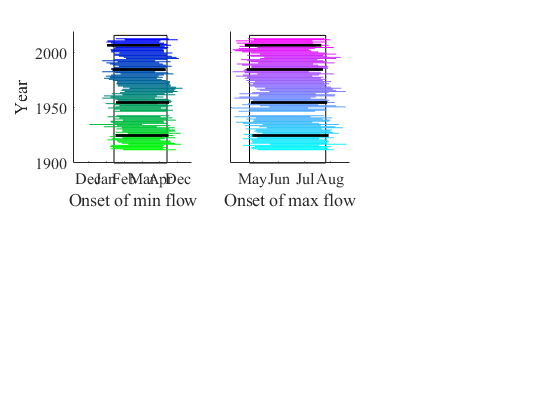

aa=3;
subplot(2,3,1)
area([mean(A(:,aa)) mean(A(:,aa))+89], [2016 2016],'FaceColor','none');
hold 'on'
% area([mean(all_Ind_max(1,1:70)) mean(all_Ind_max(1,1:70))+89], [1980 1980]);
% hold 'on'
% area([mean(all_Ind_max(1,71:end)) mean(all_Ind_max(1,71:end))+89], [1980 2016];
% 
% hold 'on'
% plot()
ylim([1900 2020]);
xlim([50 250]);
a=0;
b=1;
c=0;
for i=1:size(A(:,1))-1
    a=a;
    b=b-0.01;
    c=c+0.01;
    plot([A(i,aa) A(i,aa)+89],[A(i,1) A(i,1)],"Color",[a b c])
end
plot([mean(A(1:30,aa)) mean(A(1:30,aa))+89], [1925 1925],'lineWidth',2,'Color','k');
plot([mean(A(31:60,aa)) mean(A(31:60,aa))+89], [1955 1955],'lineWidth',2,'Color','k');
plot([mean(A(61:90,aa)) mean(A(61:90,aa))+89], [1985 1985],'lineWidth',2,'Color','k');
plot([mean(A(91:end,aa)) mean(A(91:end,aa))+89], [2007 2007],'lineWidth',2,'Color','k');
set(gca,'XTick',[76 106 136 166 196 226],'XTickLabel',...
    {'Dec','Jan','Feb','Mar','Apr'});
box('off')
xlabel('Onset of min flow')
ylabel('Year')
set(gca,'FontSize',12,'FontName','Times New Roman')


subplot(4,3,3)
bar(A(1:end-1,3),'FaceColor',[0.121 0.858 0.937],'EdgeColor','none')

P=polyfit(year_numbers(:,1),A(1:end-1,3),1);
yfit = P(1)*year_numbers(:,1)+P(2);
hold on;
plot(year_numbers(:,1),yfit,'k-.');


V_Pol=A(1:end-1,3);
alpha_Pol=0.05;
[H_Pol,p_value_Pol]=Mann_Kendall(V_Pol,alpha_Pol)

H_Pol = logical
   0


p_value_Pol = 0.1875

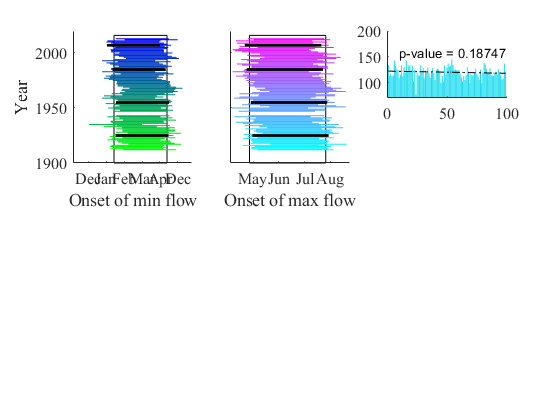

text1=['p-value = ' num2str(p_value_Pol)];
text(10,160,text1)
ylim([70 200]);
box('off')
set(gca,'FontSize',12,'FontName','Times New Roman')

subplot(4,3,6)
bar(A(1:end-1,2),'FaceColor',[0.9 0.45 0.1],'EdgeColor','none')

P=polyfit(year_numbers(:,1),A(1:end-1,2),1);
yfit = P(1)*year_numbers(:,1)+P(2);
hold on;
plot(year_numbers(:,1),yfit,'k-.');
set(gca,'FontSize',12,'FontName','Times New Roman')
V_Pol=A(1:end-1,2);
alpha_Pol=0.05;
[H_Pol,p_value_Pol]=Mann_Kendall(V_Pol,alpha_Pol)

H_Pol = logical
   1


p_value_Pol = 0.0181

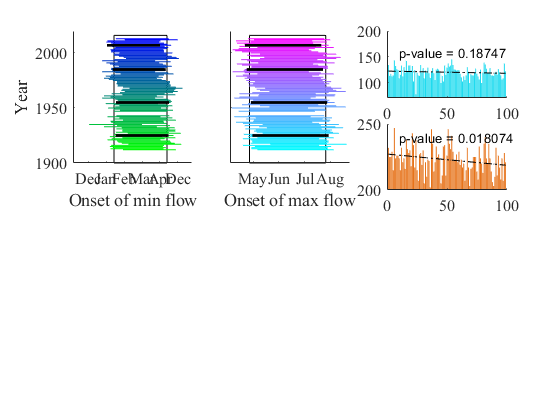

text1=['p-value = ' num2str(p_value_Pol)];
text(10,240,text1)
ylim([200 250]);
box('off')
hold 'on'

clc;
clear all;
clearvars;
A=xlsread('C:\Abolfazl\Research\PhD\cases 3mar2021\Result2\Result2.xlsx','Kukko'); 
year_numbers=[1:size(A(:,1))-2]';

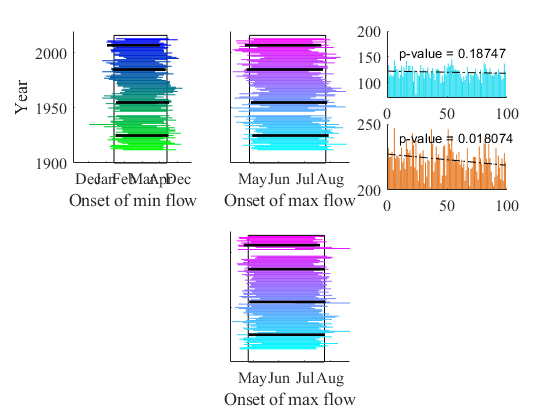


aa=2;
subplot(2,3,5)
area([mean(A(:,aa)) mean(A(:,aa))+89], [2016 2016],'FaceColor','none');
hold 'on'
% area([mean(all_Ind_max(1,1:70)) mean(all_Ind_max(1,1:70))+89], [1980 1980]);
% hold 'on'
% area([mean(all_Ind_max(1,71:end)) mean(all_Ind_max(1,71:end))+89], [1980 2016];
% 
% hold 'on'
% plot()
ylim([1900 2020]);
xlim([200 340]);
a=0;
b=1;
for i=1:size(A(:,1))-2
    a=a+0.01;
    b=b-0.01;
    c=1;
    plot([A(i,aa) A(i,aa)+89],[A(i,1) A(i,1)],"Color",[a b c])
end
plot([mean(A(1:30,aa)) mean(A(1:30,aa))+89], [1925 1925],'lineWidth',2,'Color','k');
plot([mean(A(31:60,aa)) mean(A(31:60,aa))+89], [1955 1955],'lineWidth',2,'Color','k');
plot([mean(A(61:90,aa)) mean(A(61:90,aa))+89], [1985 1985],'lineWidth',2,'Color','k');
plot([mean(A(91:end,aa)) mean(A(91:end,aa))+89], [2007 2007],'lineWidth',2,'Color','k');
set(gca,'XTick',[197 227 257 287 317 347],'XTickLabel',...
    {'Apr','May','Jun','Jul','Aug','Sep'},'YTickLabel',{'','','','','','',''});
box('off')
xlabel('Onset of max flow')
set(gca,'FontSize',12,'FontName','Times New Roman')

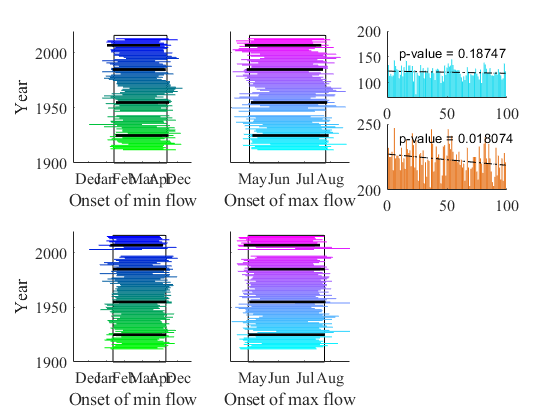

aa=3;
subplot(2,3,4)
area([mean(A(:,aa)) mean(A(:,aa))+89], [2016 2016],'FaceColor','none');
hold 'on'
% area([mean(all_Ind_max(1,1:70)) mean(all_Ind_max(1,1:70))+89], [1980 1980]);
% hold 'on'
% area([mean(all_Ind_max(1,71:end)) mean(all_Ind_max(1,71:end))+89], [1980 2016];
% 
% hold 'on'
% plot()
ylim([1900 2020]);
xlim([50 250]);
a=0;
b=1;
c=0;
for i=1:size(A(:,1))-2
    a=a;
    b=b-0.01;
    c=c+0.01;
    plot([A(i,aa) A(i,aa)+89],[A(i,1) A(i,1)],"Color",[a b c])
end
plot([mean(A(1:30,aa)) mean(A(1:30,aa))+89], [1925 1925],'lineWidth',2,'Color','k');
plot([mean(A(31:60,aa)) mean(A(31:60,aa))+89], [1955 1955],'lineWidth',2,'Color','k');
plot([mean(A(61:90,aa)) mean(A(61:90,aa))+89], [1985 1985],'lineWidth',2,'Color','k');
plot([mean(A(91:end,aa)) mean(A(91:end,aa))+89], [2007 2007],'lineWidth',2,'Color','k');
set(gca,'XTick',[76 106 136 166 196 226],'XTickLabel',...
    {'Dec','Jan','Feb','Mar','Apr'});
box('off')
xlabel('Onset of min flow')
ylabel('Year')
set(gca,'FontSize',12,'FontName','Times New Roman')

subplot(4,3,9)
bar(A(1:end-2,3),'FaceColor',[0.121 0.858 0.937],'EdgeColor','none')

P=polyfit(year_numbers(:,1),A(1:end-2,3),1);
yfit = P(1)*year_numbers(:,1)+P(2);
hold on;
plot(year_numbers(:,1),yfit,'k-.');

V_Pol=A(1:end-2,3);
alpha_Pol=0.05;
[H_Pol,p_value_Pol]=Mann_Kendall(V_Pol,alpha_Pol)

H_Pol = logical
   0


p_value_Pol = 0.7578

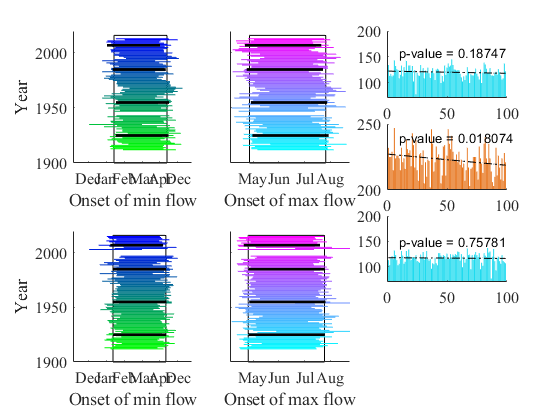

text1=['p-value = ' num2str(p_value_Pol)];
text(10,150,text1)
ylim([70 200]);
box('off')
set(gca,'FontSize',12,'FontName','Times New Roman')

subplot(4,3,12)
bar(A(:,2),'FaceColor',[0.9 0.45 0.1],'EdgeColor','none')

P=polyfit(year_numbers(:,1),A(1:end-2,2),1);
yfit = P(1)*year_numbers(:,1)+P(2);
hold on;
plot(year_numbers(:,1),yfit,'k-.');

V_Pol=A(1:end-2,2);
alpha_Pol=0.05;
[H_Pol,p_value_Pol]=Mann_Kendall(V_Pol,alpha_Pol)

H_Pol = logical
   0


p_value_Pol = 0.2336

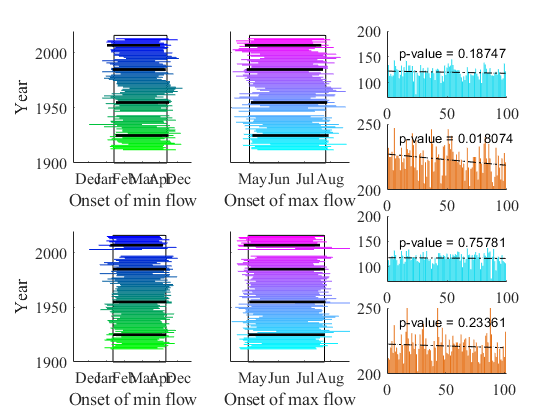

text1=['p-value = ' num2str(p_value_Pol)];
text(10,240,text1)
ylim([200 250]);
box('off')
set(gca,'FontSize',12,'FontName','Times New Roman')